% Problem 7

In previous part, we start from the motion constraints, such as spinining contraints and sliding contraints, which resulted from wheels, to get the relationship between the robot speed ( in world frame) and wheel angular speed.

Based on our discovery, we can specify how fast robot should move in world frame and calculate wheel speed in order to achieve the wanted effect.

Then, combining the forward command and turn command, we come up with a more intergated motion command.

If we go further into consideration, we will notice that what those things really do is to generate wheel speed to move SMR.

The position or velocity is not fed back into the control, so they really are of open-loop control model.

The new algorithm is based on a completely different law.

    0.5000         0         0



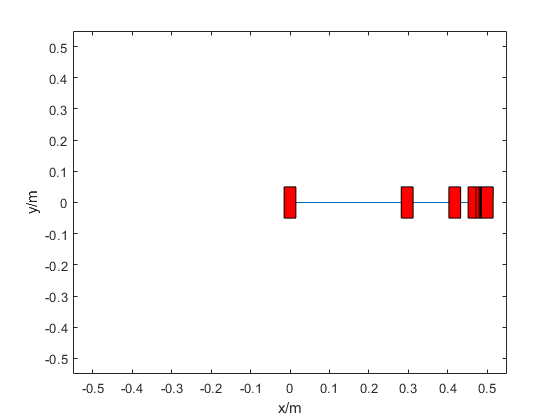

    0.5000    0.5000         0



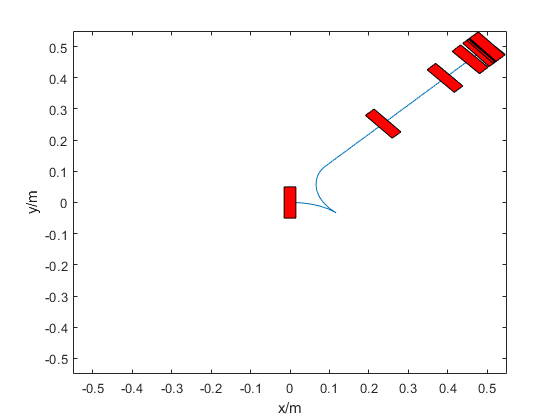

    0.5000   -0.5000   -1.5708



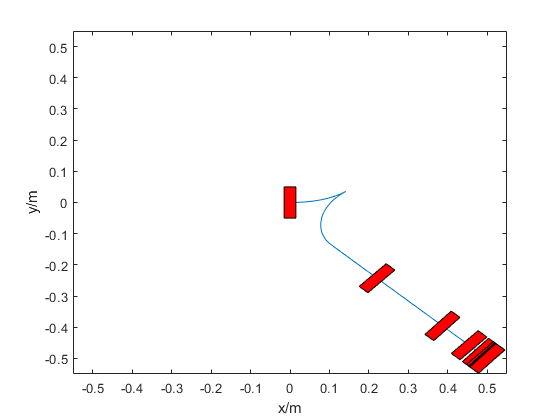

         0    0.5000   -3.1416



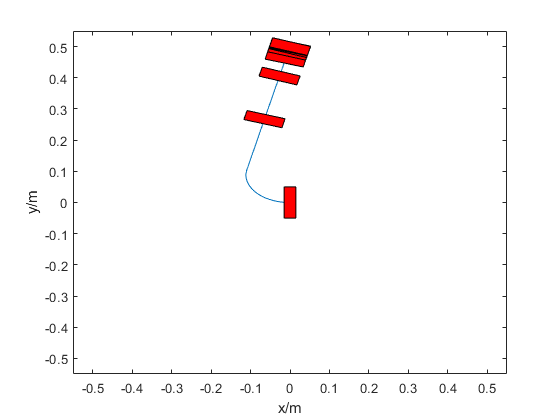

         0         0    1.5708



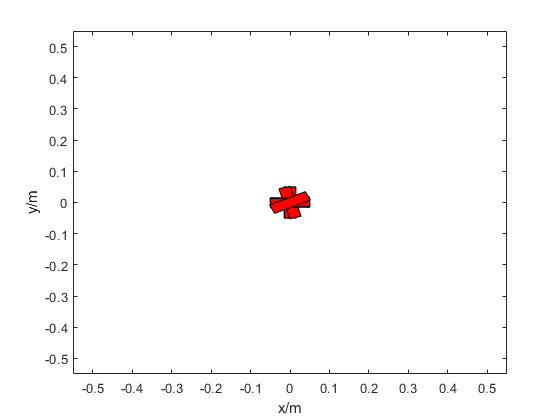

         0   -0.5000         0



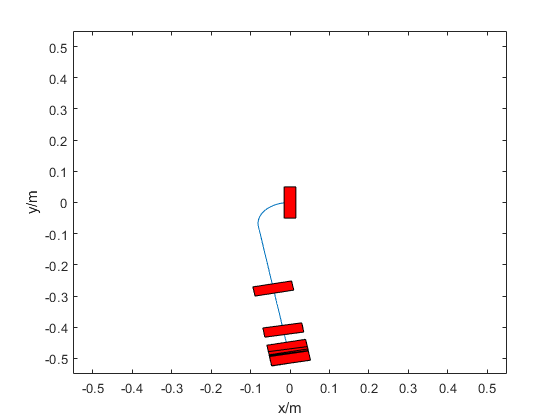

   -0.5000    0.5000         0



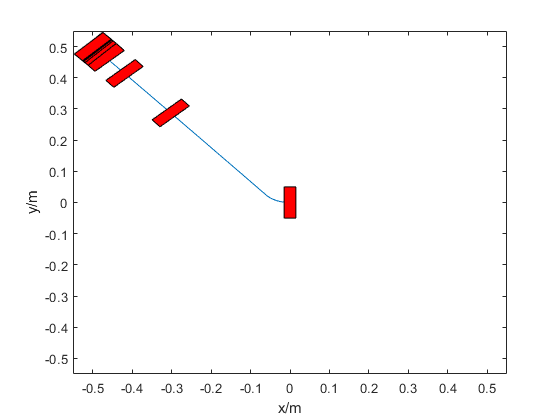

   -0.5000         0         0



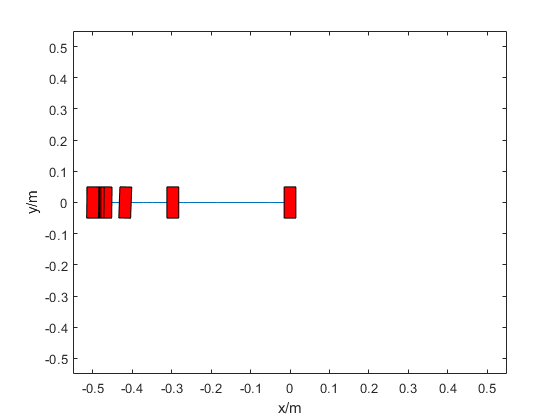

   -0.5000   -0.5000   -3.1416



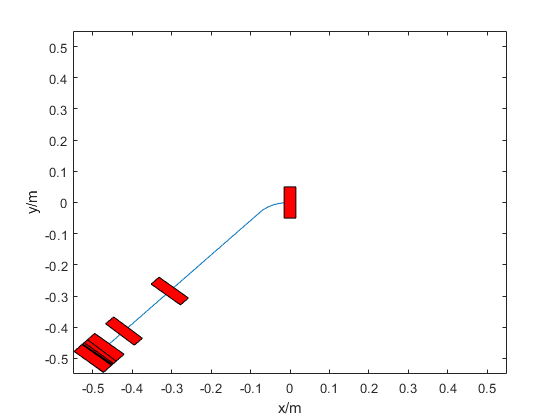

% Problem 8
clear all
Ts = 0.01;
robotpar = [0.26 0.035 0.035];
poses = [0.5 0 0;0.5 0.5 0;0.5 -0.5 -pi/2;0 0.5 -pi;0 0 pi/2;0 -0.5 0;
     -0.5 0.5 0;-0.5 0 0;-0.5 -0.5 -pi];

pose = [0 0 0];
for i = 1:9
    disp(poses(i,:))
    figure
    grid on
    hist = Move(pose, poses(i,:), robotpar,Ts,3000);
    plot(hist(:,1), hist(:,2))
    plot_hist(hist, 10)
    axis([-0.55 0.55 -0.55 0.55])
    xlabel('x/m')
    ylabel('y/m')
    hold off
end

syms v w theta
speed_I = [v*cos(theta);v*sin(theta);w]

$$speed\_I = \left(\begin{array}{c} v\,\cos\left(\theta \right)\\ v\,\sin\left(\theta \right)\\ w \end{array}\right)$$

theta = theta

$$theta = \theta$$

simplify(Cal_ws(theta, speed_I, robotpar))

$$ans = \left(\begin{array}{cc} \frac{200\,v}{7}-\frac{26\,w}{7} & \frac{200\,v}{7}+\frac{26\,w}{7} \end{array}\right)$$

% r--first; l--second

syms theta
Rot(theta)

$$ans = \left(\begin{array}{ccc} \cos\left(\theta \right) & \sin\left(\theta \right) & 0\\ -\sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

function m = Rol_cstr(p) 
    % p: [alpha, beta, l] wheel parameters
    m = [sin(p(1)+p(2)) -cos(p(1)+p(2)) -p(3)*cos(p(2))];
end  
% ------------------------------------------------------------------------------------------------------%
function m = Sld_cstr(p) 
    % p: [alpha, beta, l] wheel parameters
    m = [cos(p(1)+p(2)) sin(p(1)+p(2)) p(3)*sin(p(2))];
end
% ------------------------------------------------------------------------------------------------------%
function m = Rot(theta) 
    % Rotation matrix from world to robot frame
    m = rotz(-theta);
end
% ------------------------------------------------------------------------------------------------------%
function ws = Cal_ws(theta, speed_I, robotpar)
    % robotpar: wheelseparation, radius rightwheel, radius left wheel
    radius_l = robotpar(3);
    radius_r = robotpar(2);
    % left and right wheel parameters
    p_left = [pi/2 0 robotpar(1)/2];
    p_right = [-pi/2 pi robotpar(1)/2];
    speed_r = Rol_cstr(p_right)*Rot(theta)*speed_I/radius_r; % Right wheel speed
    speed_l = Rol_cstr(p_left)*Rot(theta)*speed_I/radius_l; % Left wheel speed
    ws = [speed_l speed_r];
end
% ------------------------------------------------------------------------------------------------------%
function newpose = kinupdate(pose, robotpar, ts, wheelspeed)
    Rt = Rot(pose(3)); 
    p_left = [pi/2 0 robotpar(1)/2]; 
    p_right = [-pi/2 pi robotpar(1)/2]; 
    Cstr = [Rol_cstr(p_left); Rol_cstr(p_right); Sld_cstr(p_left)];
    M = diag([robotpar(3) robotpar(2) 1]);
    v = [wheelspeed(2);wheelspeed(1);0];
    speed_I = inv(Rt)*inv(Cstr)*M*v;  
    newpose = pose + ts*transpose(speed_I);
end
%-----------------------------------------Problem 7-----------------------------------------------------%
function CposeT = World2Target(Tpose, Cpose)
    CposeT = Rot(Tpose(3))*(Cpose - Tpose)';
end

function ang = angNorm(ang)
if ang>pi
    ang = ang-2*pi;
    ang = angNorm(ang);
end
if ang<-pi
    ang = ang+2*pi;
    ang = angNorm(ang);
end
end

function hist = Move(c_pose, t_pose, robotpar,ts, max_iter)
    k_rho = 0.3;
    k_a = 0.8;
    k_beta = -0.15;
    hist = zeros(1,3);
    i = 1;
    hist(i,:) = c_pose;
    for i = 1:max_iter
        % Apply the algorithm in converted frame
        pose_cvt = World2Target(t_pose, c_pose);
        dx = -pose_cvt(1);
        dy = -pose_cvt(2);
        rho = sqrt(dx*dx + dy*dy);
        theta = pose_cvt(3);
        alpha = -theta + atan2(dy, dx);
        alpha = angNorm(alpha);
        beta = - theta - alpha;
        % Check the range of 2 angles
        beta = angNorm(beta);
        if alpha>-pi/2 && alpha<pi/2
            v = k_rho * rho;
        else
            v = -k_rho * rho;
        end
        w = k_a * alpha + k_beta*beta;
        speed_t = [v*cos(theta);v*sin(theta);w];
        % Transform the calculated speed into world frame
        speed_w = Rot(-t_pose(3))*speed_t;
        theta_w = c_pose(3);
        s_w = Cal_ws(theta_w,speed_w,robotpar);
        c_pose = kinupdate(c_pose,robotpar,ts,s_w);
        i = i+1;
        hist(i,:) = c_pose;
    end
end
%----------------------------------------helpler function------------------------------------------------%
function plot_rectangle(x_coor, y_coor, angle, w, h)
    pos = [x_coor; y_coor];
    pos_1 = [-w/2;- h/2];
    pos_2 = [w/2;-h/2];
    pos_3 = [-w/2;h/2];
    pos_4 = [w/2;h/2];
    pose_1r = rot2(angle)*pos_1 + pos;
    pose_2r = rot2(angle)*pos_2 + pos;
    pose_3r = rot2(angle)*pos_3 + pos;
    pose_4r = rot2(angle)*pos_4 + pos;
    x = [pose_1r(1) pose_2r(1) pose_4r(1) pose_3r(1)];
    y = [pose_1r(2) pose_2r(2) pose_4r(2) pose_3r(2)];
    patch(x, y, 'red')
end

function plot_hist(hist, num)
    shape = size(hist);
    len = shape(1);
    step = max(5,round(len/num,0));
    if len >= 5
        for i = 1:step:len
        plot_rectangle(hist(i,1),hist(i,2),hist(i,3), 0.03,0.1)
        end
    end
end